# 4.9 Discrete controller and observer

% select the sampling time
fSamplingPeriod = 0.005;

load poles.mat
load Linear_Param.mat
poles

poles = 1.0e+02 *

  -6.6476 + 0.0000i
  -0.0508 + 0.0000i
  -0.0248 + 0.0035i
  -0.0248 - 0.0035i


A;
B = B(:,1);
C = [1 0 0 0;
    0 0 1 0];
D = 0;
contStateSpace = ss(A,B,C,D)

contStateSpace =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -435  -6.099   9.136
   x3       0       0       0       1
   x4       0    1903   62.02  -39.97
 
  B = 
           u1
   x1       0
   x2   20.58
   x3       0
   x4  -90.03
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



discreteStateSpace = c2d(contStateSpace,fSamplingPeriod);
Ad = discreteStateSpace.A

Ad =     1.0000    0.0022   -0.0000    0.0001
         0    0.1693   -0.0095    0.0174
         0    0.0124    1.0006    0.0047
         0    3.6357    0.2185    0.9242


Bd = discreteStateSpace.B

Bd =     0.0001
    0.0393
   -0.0006
   -0.1720


Cd = discreteStateSpace.C

Cd =      1     0     0     0
     0     0     1     0


D = discreteStateSpace.D

D =      0
     0


discretePoles = exp(poles*fSamplingPeriod)

discretePoles =    0.0360 + 0.0000i
   0.9749 + 0.0000i
   0.9877 + 0.0017i
   0.9877 - 0.0017i



%Plotting discrete poles
scatter(real(discretePoles),imag(discretePoles))
hold on
r = 1

r = 1

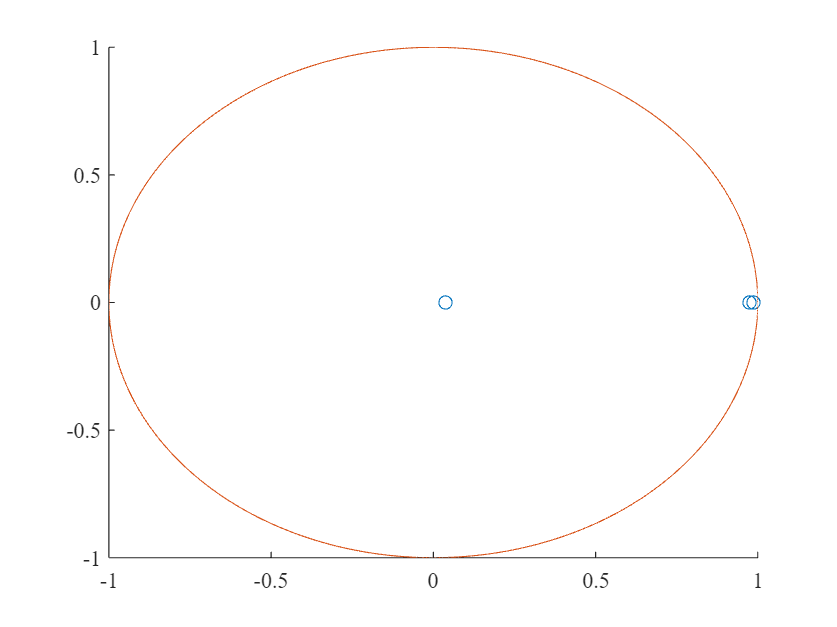

ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(xp,yp);
hold off

Controller

%State-feedback gain
Kd = place(Ad,Bd,discretePoles)

Kd =   -21.5911  -42.5518  -61.6884  -10.1567


eig(Ad-Bd*Kd)

ans =    0.0360 + 0.0000i
   0.9749 + 0.0000i
   0.9877 + 0.0017i
   0.9877 - 0.0017i


Full-state observer

factor = 4;
speed = max(abs(poles(2:4)));
contObserverPoles(1) = poles(1);
contObserverPoles(2) = -2*factor*speed; % Place pole to not disturb dominant poles
omegan = factor*speed;
zeta = 0.99;
contObserverPoles(3:4) =    [omegan*(-zeta+1i*sqrt(1-zeta^2));
                             omegan*(-zeta-1i*sqrt(1-zeta^2))];
desiredPoles = exp(contObserverPoles*fSamplingPeriod)

desiredPoles =    0.0360 + 0.0000i   0.8161 + 0.0000i   0.9042 + 0.0130i   0.9042 - 0.0130i


Ld = (place(Ad',Cd',desiredPoles))'

Ld =     0.1135    0.0052
   -1.3682    4.3732
    0.0237    0.3201
    6.3909  -15.2655


eig(Ad-Ld*Cd)

ans =    0.0360 + 0.0000i
   0.8161 + 0.0000i
   0.9042 + 0.0130i
   0.9042 - 0.0130i


Reduced order observer

T = inv([C;0 1 0 0; 0 0 0 1])

T =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1


An = inv(T)*Ad*T ;  %New A-matrix
Bn = inv(T)*Bd;     %New B-matrix
Cbacc = Cd(1,:)*T;  %Accurate
Cbnacc = Cd(2,:)*T; %Not accurate

Ayy = An(1,1); %Zero
Ayx = An(1,2:4);  %Noisy/unobserved states
Axy = An(2:4,1); % Zero
Axx = An(2:4,2:4); %Noisy/unobserved states

By = Bn(1);
Bx = Bn(2:4);

Cy = Cbnacc(1);
Cx = Cbnacc(2:4);

AA = Axx;
CC = [Ayx
      Cx];
Lpartial = ( place( AA', CC', desiredPoles(2:4) ) )';
Lacc = Lpartial(:,1);
Lnacc = Lpartial(:,2);

poles(2:4);
observerPoles = eig(AA-Lpartial*CC)

observerPoles =    0.8161 + 0.0000i
   0.9042 + 0.0130i
   0.9042 - 0.0130i



M1d = Axx-Lacc*Ayx-Lnacc*Cx

M1d =     0.8187    0.0205    0.0050
    0.0213    0.9860    0.0398
   -0.0225   -0.1805    0.8198


M2d = Bx-Lacc*By

M2d =    -0.0001
    0.0897
   -0.4075


M3d = Axy-Lacc*Ayy-Lnacc*Cy

M3d = 1.0e+03 *

    0.0038
    0.3765
   -1.7591


M4d = Lnacc

M4d =     0.1818
   -0.0443
    0.3036


M5d = Lacc

M5d = 1.0e+03 *

   -0.0038
   -0.3765
    1.7591


M6d = T(:,1)

M6d =      1
     0
     0
     0


M7d = T(:,2:4)

M7d =      0     0     0
     0     1     0
     1     0     0
     0     0     1


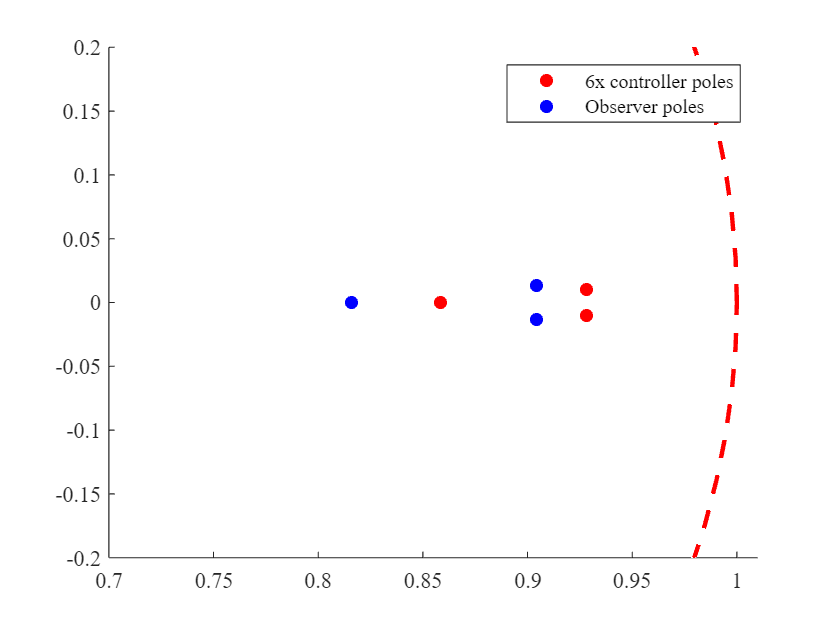



scatter(real(discretePoles.^6),imag(discretePoles.^6),"red","filled")
hold on
scatter(real(desiredPoles),imag(desiredPoles),"blue","filled")
viscircles([0 0], 1,'LineStyle','--');
hold off
legend("6x controller poles","Observer poles")
xlim([0.7 1.01])
ylim([-0.2 0.2])